**Author:    Michal Szabo**

**Date:        10.12.2021**

## Practice 3. Optimal Control

Given the model of a DC motor expressed in discrete-time as follows


$$\begin{array}{l}
x_1 \left(k+1\right)=x_1 \left(k\right)+x_2 \left(k\right)+u\left(k\right)\\
x_2 \left(k+1\right)=x_1 \left(k\right)
\end{array}$$


where $x_1 \left(k\right)$ is the angular speed and $x_2 \left(k\right)$ is the position, an optimal controller of LQR type is wanted to be designed.

### Activity 1. Numerical/Analytical Optimization Method

The goal of this activity is to implement an LQR controller for the DC motor by using numerical/optimizaton approaches. 

#### 1-2. Numerical solution (quadprog slover)

 1. To formulate this optimization problem mathematically in Matlab with YALMIP extension we first create A and B matrices, that represent our model. Then we set the weights where $Q=1$, but in our case we have 2 states, so it's a 2x2 diagonal matrix $Q=\left\lbrack 1,0;0,1\right\rbrack$ and $R=1$, beacuse we only have one input. We consider that the initial condition is $x_0 =\left\lbrack 1,1\right\rbrack$ and the control horizon $N=10$.

A=[1, 1; 1,0];  % system matrix
B=[1;0];        % control matrix

% ***Pareto Plot***
p = 0;
for e=0.1:0.1:2    % for calculation of error with different weights multiplying them by e
p=p+1;
Q=eye(2)*e;
% Q=eye(2);   % weight of states in obj function
R=1;        % weight of control action in obj function
N=10;       % control horizon 

nu = 1; % number of inputs (voltage)
nx = 2; % number of states (angular speed and position)

Because we have a finite control horizon, we can initialize the input and the states using *sdpvar *function, where for the input we put an array with number of inputs and an array with ones with a length of $N$ and for the states an array with number of states and an array with ones, but in this case with a length of $N+1$, because of the intial state. We created these arrays with *repmat* function. Then we introduce our initial condition to the model.

u = sdpvar(repmat(nu,1,N),repmat(1,1,N));
x = sdpvar(repmat(nx,1,N+1),repmat(1,1,N+1));

x{1}=[1;1]; % initial condition

Knowing the objective function:


$$\min_{u\left(1\right),\ldotp \ldotp \ldotp ,u\left(N\right)} \left(x^T \left(N\right)\cdot \;S\cdot \;x\left(N\right)+\sum_{k=1}^N \left(\textrm{𝑥𝑇}\left(\textrm{𝑘}\right)\cdot \textrm{𝑄}\cdot \textrm{𝑥}\left(\textrm{𝑘}\right)+\textrm{𝑢𝑇}\left(\textrm{𝑘}\right)\cdot \textrm{𝑅}\cdot \textrm{𝑢}\left(\textrm{𝑘}\right)\right)\right)$$


And constraints:


$$x\left(k+1\right)=A\cdot x\left(k\right)+B\cdot u\left(k\right)\;\;\;\;\;\;\;k=1,\cdot \cdot \cdot \;,N+1$$



$$x\left(1\right)=x_1 \;\;\;\;\;\;\textrm{known}$$


Where we can see that our objective function expresses the predicted states as a function of a given current state and the future control sequence. We simply loop the simulation equations and gather constraints and objective terms along the horizon using the following code:

%Initialization
constraints = [];
objective = 0;

% Looping simulation equations
for k = 1:N
    objective = objective + x{k}'*Q*x{k} + u{k}'*R*u{k};
    constraints = [constraints, x{k+1} == A*x{k} + B*u{k}];
end

 2. Once the constraints and objective function have been generated, we can solve the optimization problem using numerical methods precisely *quadprog *solver**.**

options = sdpsettings('solver', 'quadprog');
optimize(constraints,objective,options);

We get the control signal and states form *xopt *and *uopt *using the following code.

xopt(:,1)=[1;1];    % setting the initial condition again

% Calculus of u and x
for k=1:N
 uopt(k)=value(u{k});
 xopt(:,k+1)=A*xopt(:,k)+B*uopt(k);
end
% Saving control action and states
if Q == eye(2)
    u_num = uopt;
    x_num = xopt;

Plotting the results with weights $Q=1$ and $R=1$.


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

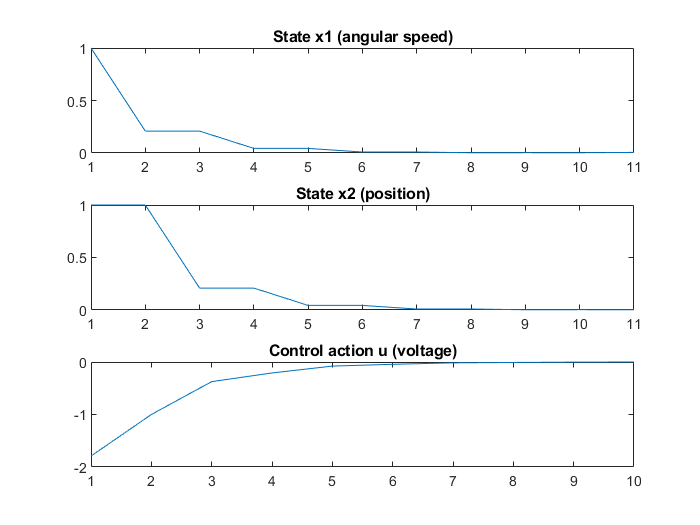


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

figure
subplot(3,1,1); plot(xopt(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(xopt(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(uopt), title('Control action u (voltage)')
end

Je = 0; 
Ju = 0; 
for k = 1:N 
    Je = Je + value(x{k}')*value(x{k});
    Ju = Ju + value(u{k}')*value(u{k});
end

all_Je(p) = Je;
all_Ju(p) = Ju;
end % end of calculation of error with different weights multiplying them by e

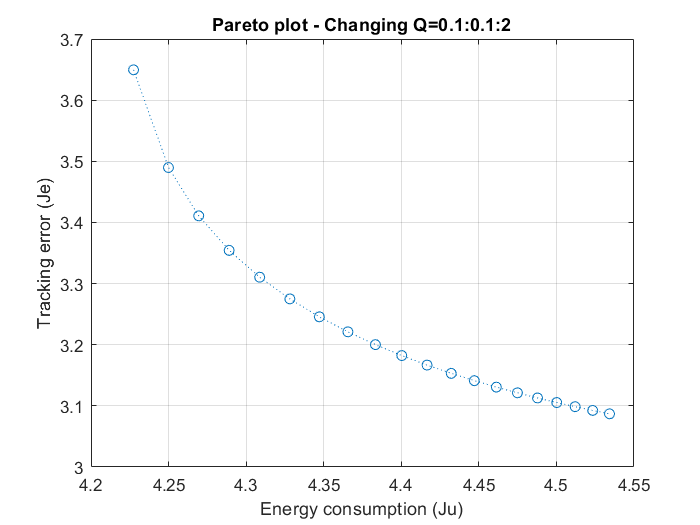

figure
plot(all_Ju,all_Je,'o:')
title('Pareto plot - Changing Q=0.1:0.1:2')
xlabel('Energy consumption (Ju)')
ylabel('Tracking error (Je)')
grid on

We can see from the Pareto plot that tracking error is inversly proportional to energy consumption. This makes sense because the smaller the error we want, the more energy consumption there is gonna be in order to lower the error. We need to find the optimal value that fits the requirements. 

#### Analytical solution. Ricatti method (exact solution) 

3. Now we will try to verify the results obtained with the numerical method using the Ricatti method. To do that we will need optimal control equations obtained from analytical solution:


$$u\left(k\right)=-K\left(k\right)\cdot x\left(k\right)$$


where


$$K\left(k\right)=R^{-1} {\cdot B}^T \cdot \left(A^T {\left.\right)}^{-1} \cdot \left\lbrack P\left(k\right)-Q\right\rbrack \right.$$


And the Ricatti equation:


$$P\left(k\right)=Q+A^T \cdot P\left(k+1\right)\cdot \left\lbrack I+B\cdot R^{-1} \cdot B^T \cdot P\left(k+1\right){\left.\right\rbrack }^{-1} \cdot A\right.$$


where


$$P\left(N\right)=S$$


So we are gonna use the same variables as before, but the only thing we are gonna add is the weight of final state:

A=[1, 1; 1,0];  % system matrix
B=[1;0];        % control matrix
Q=eye(2);   % weight of states in obj function
R=1;        % weight of control action in obj function
N=10;       % control horizon 
S=Q;    % weight of final state in obj function

Then we inicialize the arrays.

%Initialization
P=zeros(2,2,N+1);   % P matrix
K=zeros(1,2,N);     % gain
u=zeros(1,N);       % control action
x=zeros(2,N+1);     % states
x(:,1)=[1,1];       % initial conditions

And now we loop in a recursive way in order to calculate all the values of $P$ and $K$.

% Riccati equation backwards recursion
P(:,:,N+1)=S;
for k=N:-1:1
 P(:,:,k)=Q+A'*P(:,:,k+1)*inv(eye(2)+B*inv(R)*B'*P(:,:,k+1))*A;
 K(:,:,k)=inv(R+B'*P(:,:,k+1)*B)*B'*P(:,:,k+1)*A;
end

Now we can calculate input and the states.

% Calculus of u and x
for k=1:N
 u(k)=-K(:,:,k)*x(:,k);
 x(:,k+1)=A*x(:,k)+B*u(k);
end
% Saving control action and states
u_ex = u;
x_ex = x;

In order to plot the gain of each state we needed to change it from 3 dimensional to 2 dimensional matrix.

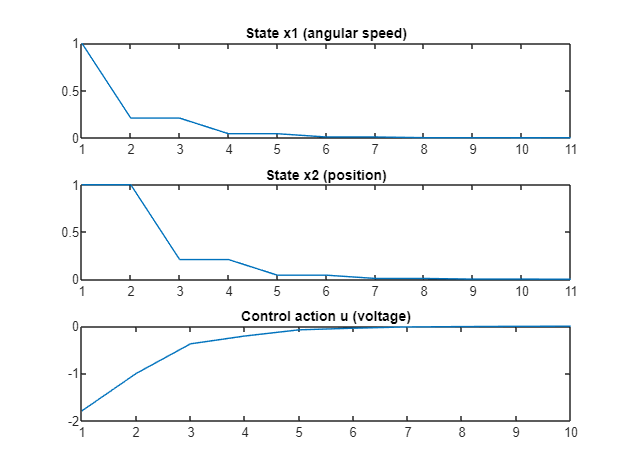

figure
subplot(3,1,1); plot(x_ex(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(x_ex(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(u_ex), title('Control action u (voltage)')

In order to plot the gain of each state we needed to change it from 3 dimensional to 2 dimensional matrix.

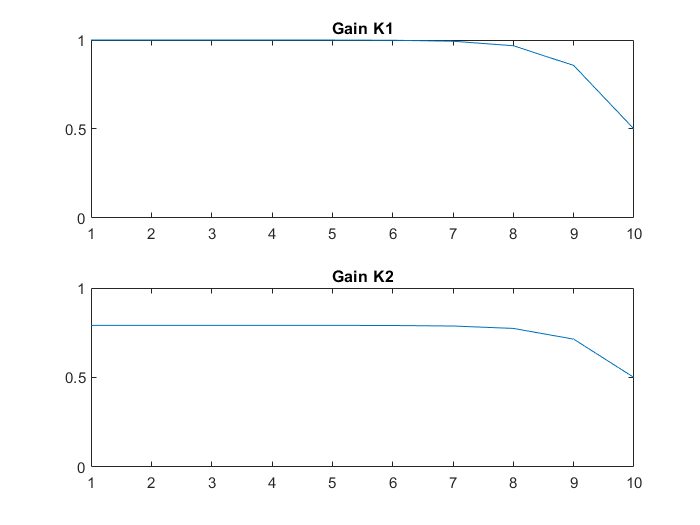

K1 = squeeze(K(1,1,:));
K2 = squeeze(K(1,2,:));
figure
subplot(2,1,1), plot(K1), axis([1 N 0 1]), title('Gain K1')
subplot(2,1,2), plot(K2), axis([1 N 0 1]) ,title('Gain K2')

#### Analytical solution. Ricatti method (steady state solution)

Checking that using the steady state solution, the result is quite close to the one obtained using the exact solution. The steady state solution is a Ricatti approximation where K and P are the same for each k. The equations are the following:


$$u\left(k\right)=-K_{\textrm{SS}} \cdot x\left(k\right)$$



$$K_{\textrm{SS}} =R^{-1} \cdot B^T \cdot {\left(A^T \right)}^{-1} \cdot \left\lbrack P_{\textrm{SS}} -Q\right\rbrack$$



$$P_{\textrm{SS}} =Q+A^T \cdot P\cdot \left(I+B\cdot R^{-1} \cdot B^T \cdot P\right)\cdot A_S$$


We initialize parameters as before and then can calculate $K$ and $P$ manually:

% Steady state
P=zeros(2,2);
Pman=Q+A'*P*inv(eye(2)+B*inv(R)*B'*P)*A;
while sum(sum(abs(P-Pman)))>0.0001
     P=Pman;
     Pman=Q+A'*P*inv(eye(2)+B*inv(R)*B'*P)*A;
end
Pman

Pman =     3.7913    1.0000
    1.0000    1.7913


Kman = Pman(2,:)

Kman =     1.0000    1.7913


Or using Matlab functions *dare *for $P$ and *dlqr *for $K\ldotp$

Pss=dare(A,B,Q,R)

Pss =     3.7913    1.0000
    1.0000    1.7913


Kss=dlqr(A,B,Q,R)

Kss =     1.0000    0.7913


We can see that gain for angular speed is 1 and gain for position is 0.7913 in both calculations.

% Act1.4 Riccati.m Analytical approximate optimal solution

A=[1, 1; 1,0];  % system matrix
B=[1;0];        % control matrix
Q=eye(2);   % weight of states in obj function
S=Q;        % weight of final state in obj function
R=1;        % weight of control action in obj function
N=10;       % horizon

%Initialization
P=zeros(2,2,N+1);   % P matrix
K=zeros(1,2,N);     % gain
u=zeros(1,N);       % control action
x=zeros(2,N+1);     % states
x(:,1)=[1,1];       % initial conditions

% Solve Riccati equation with steady state approximation
Pss=dare(A,B,Q,R);
Kss=dlqr(A,B,Q,R);

Finally, the control signal and the states are computed using the following code:

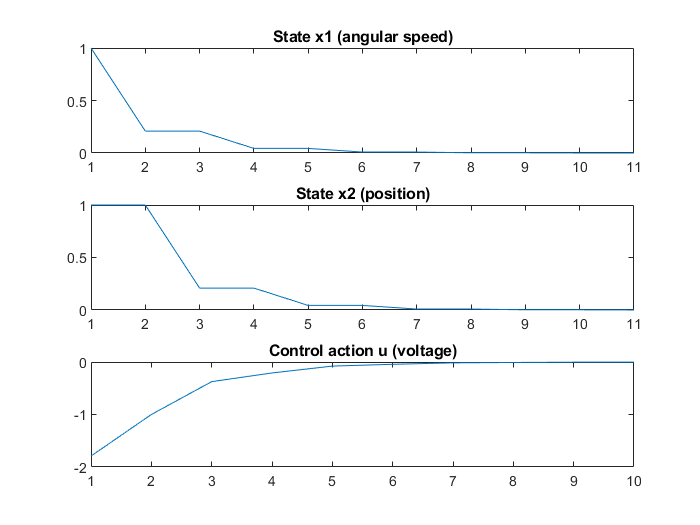

% Calculus of u and x
for k=1:N
    u(k)=-Kss*x(:,k);
    x(:,k+1)=A*x(:,k)+B*u(1,k);
end
% Saving control action and states
u_aprox = u;
x_aprox = x;

figure
subplot(3,1,1); plot(x_aprox(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(x_aprox(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(u_aprox), title('Control action u (voltage)')

Now we can calculate the difference between ricatti exact and steady state solution to see how similar they are.

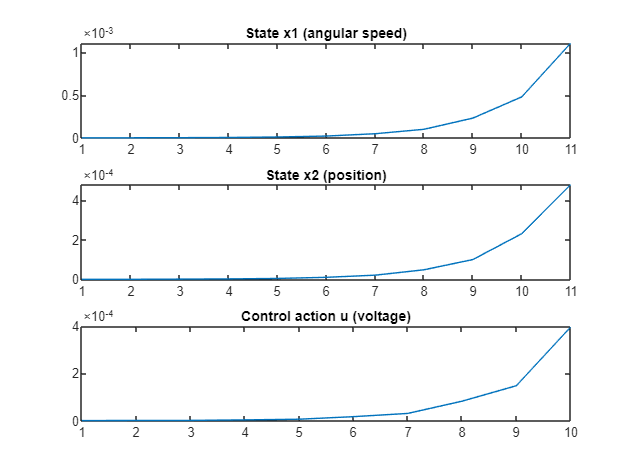

diff_x = x_ex-x_aprox;
diff_u = u_ex-u_aprox;
figure
subplot(3,1,1); plot(diff_x(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(diff_x(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(diff_u), title('Control action u (voltage)')

From the graphs we can see that the difference is really small but is increasing with steps. Steady state solution alows us faster optimization with quite a small error.

#### **Analytical solution. Ricatti method (steady state solution) using LMI**

In this case the solution is going to be obtained by solving Linear Matrix Inequalities (LMI) using the *sedumi *solver that we needed to install.

The objective is to minimize $\gamma$, subjected to the following constraints:


$$\left\lbrack \begin{array}{cc}
\gamma I & I\\
I & Y
\end{array}\right\rbrack \ge 0$$



$$\left\lbrack \begin{array}{cccc}
-Y & {\textrm{YA}}^T -W^T B^T  & {\textrm{YH}}^T  & W^T \\
\textrm{AY}-\textrm{BW} & -Y & 0 & 0\\
\textrm{HY} & 0 & -I & 0\\
W & 0 & 0 & -R^{-1} 
\end{array}\right\rbrack <0$$


where:


$$Y=P_{\textrm{SS}}^{-1}$$
        
$$W=K_{\textrm{SS}} Y$$
        
$$Q=H^T H$$


In this case we know that $I$ and $H$ are identity matrices:

I = eye(2);
H = eye(2);

Then we initialize matrices $Y$ and $W$ and also the control states.

%Initialization
Y = sdpvar(2,2);
W = sdpvar(1,2,'full');
u=zeros(1,N);   % control action
x=zeros(2,N+1); % states
x(:,1)=[1,1];   % initial condition

We define our objective function and constraints.

gamma = sdpvar(1,1);    % objective function
constraints=[Y>=0];
constraints=[constraints, [gamma*I I;I Y]];
constraints=[constraints, [  -Y       Y*A'-transpose(W)*B'     Y*H'      transpose(W);
                           A*Y-B*W            -Y            zeros(2,2)   zeros(2,1);
                             H*Y           zeros(2,2)            -I      zeros(2,1);
                              W            zeros(1,2)       zeros(1,2)    -R^(-1)] <=0];

And we solve the problem using *sedumi *solver*.*

options = sdpsettings('solver', 'sedumi');
optimize(constraints,gamma,options) 

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 14, dim = 70, blocks = 4
nnz(A) = 28 + 0, nnz(ADA) = 32, nnz(L) = 19
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.76E+00 0.000
  1 :  -9.15E-01 1.45E+00 0.000 0.2510 0.9000 0.9000   1.63  1  1  2.9E+00
  2 :  -1.38E+00 5.29E-01 0.000 0.3658 0.9000 0.9000   1.17  1  1  9.4E-01
  3 :  -2.11E+00 2.05E-01 0.000 0.3866 0.9000 0.9000   0.51  1  1  4.7E-01
  4 :  -2.93E+00 7.16E-02 0.000 0.3500 0.9000 0.9000   0.61  1  1  1.8E-01
  5 :  -3.40E+00 3.10E-02 0.000 0.4331 0.9000 0.9000   0.58  1  1  9.4E-02
  6 :  -3.86E+00 9.47E-03 0.000 0.3056 0.9000 0.9000   0.70  1  1  3.1E-02
  7 :  -4.05E+00 3.72E-03 0.000 0.3930 0.9000 0.9000   0.75  1  1  1.4E-02
  8 :  -4.19E+00 3.65E-04 0.000 0.0979 0.9900 0.9900   0.91  1  1  1.4E-03
  9 :  -4.20E+00 7.65E-05 0.000 0.2099 0.9000 0.9000   0.96  1  1  3.0E-04
 10 :  -4.21E+00 

ans = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.11.0.1769968 (R2021b)'
       yalmiptime: 0.0607
       solvertime: 0.1893
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


To calculate gain we can use  equation $W=K_{\textrm{SS}} \cdot Y$ and express gain $K_{\textrm{SS}} =W\cdot Y^{-1}$.

Kss= value(W)*inv(value(Y))

Kss =     1.0000    0.7913


We can see that the gain in LMI method is the same as the gain in Steady state.

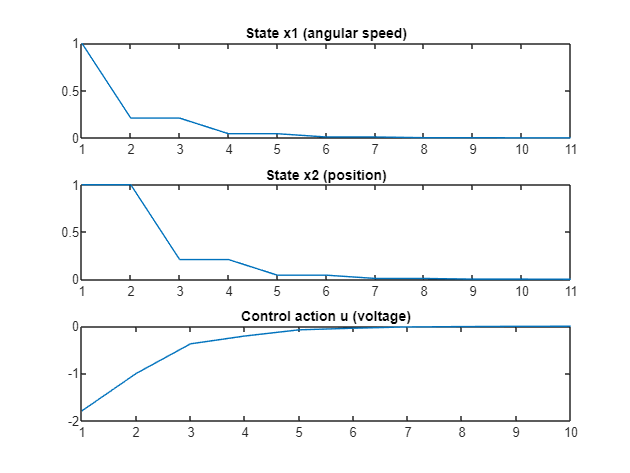

%Calculus of u and x
for k=1:N
    u(k)=-Kss*x(:,k);
    x(:,k+1)=A*x(:,k)+B*u(1,k);
end
% Saving control action and states
u_LMI = u;
x_LMI = x;

figure
subplot(3,1,1); plot(x(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(x(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(u), title('Control action u (voltage)')

Now we can calsulate if the LMI method produces the same result as steady state.

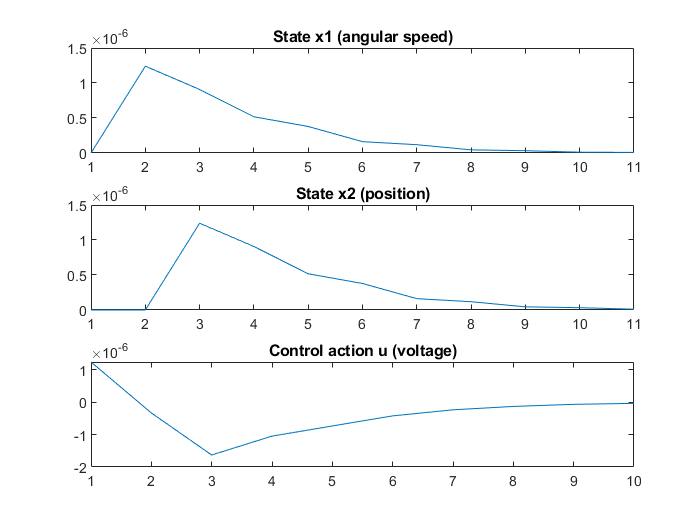

diff_x = x_LMI-x_aprox;
diff_u = u_LMI-u_aprox;

figure
subplot(3,1,1); plot(diff_x(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(diff_x(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(diff_u), title('Control action u (voltage)')

The biggest difference is in the beginning and is getting smaller with steps

#### Numerical solution with constraints

Now, we include a constraint in the controller such that


$$u\left(k\right)\epsilon \left\lbrack -1\ldotp 5,1\ldotp 5\right\rbrack$$


And check how does this affects the results obtained previously. 

Again, first the control action and the states are initialized:

nu = 1;             % number of inputs (voltage)
nx = 2;             % number of states (position and velocity)
u = sdpvar(repmat(nu,1,N),repmat(1,1,N));
x = sdpvar(repmat(nx,1,N+1),repmat(1,1,N+1));
x{1}=[1;1];         % initial conditions

And then the objective function and constraints are defined, where we add aditional 2 lines for constraints.

constraints = [];
objective = 0;
% Objective function and constraints
for k = 1:N
    objective = objective + x{k}'*Q*x{k} + u{k}'*R*u{k};
    constraints = [constraints, x{k+1} == A*x{k} + B*u{k}];
    constraints = [constraints, u{k} >= -1.5];
    constraints = [constraints, u{k} <= +1.5];
end

We solve the optimiyation problem using *quadprog *solver.

options = sdpsettings('solver', 'quadprog');
optimize(constraints,objective,options);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


And compute the control action signal and states.

xopt(:,1)=[1;1];
%Calculus of u and x 
for k=1:N 
    uopt(k)=value(u{k});
    xopt(:,k+1)=A*xopt(:,k)+B*uopt(k);
end 

In the following graph we plot numerical solution without constraints and with constraints.

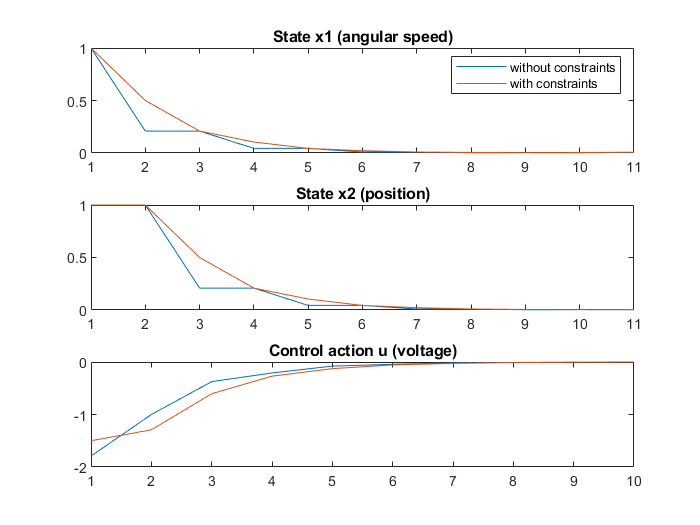

figure
subplot(3,1,1); plot(x_num(1,:)), title('State x1 (angular speed)'),hold on
plot(xopt(1,:)),hold off
legend('without constraints','with constraints')
subplot(3,1,2); plot(x_num(2,:)), title('State x2 (position)'),hold on
plot(xopt(2,:)),hold off
subplot(3,1,3); plot(u_num), title('Control action u (voltage)'),hold on
plot(uopt),hold off

We can see that the with the constraints we don't have such a big step changees in states and it's more gradual.

####  6. Finally, simulate the DC motor including some disturbance $w\left(k\right)$ that is assumed to be Gaussian with zero mean and variance 0.1 as follows

a)     $\begin{array}{l}
x_1 \left(k+1\right)=x_1 \left(k\right)+x_2 \left(k\right)+u\left(k\right)+w\left(k\right)\\
x_2 \left(k+1\right)=x_1 \left(k\right)
\end{array}$

First we introduce the optimization problem.

A=[1, 1; 1,0];
B=[1;0];        % control matrix
Q=eye(2)*2;     % weight of states in obj function
R=1;            % weight of control action in obj function
N=100;          % horizon 

nu = 1; % number of inputs
nx = 2; % number of states

u = sdpvar(repmat(nu,1,N),repmat(1,1,N));
x = sdpvar(repmat(nx,1,N+1),repmat(1,1,N+1));
% x{1}=[1;1];

We create a disturbance that is gaussian with zero mean using normpdf function.

constraints = [];
objective = 0;
for k = 1:N
    objective = objective + x{k}'*Q*x{k} + u{k}'*R*u{k};
    constraints = [constraints, x{k+1} == A*x{k} + B*u{k}];
end

options = sdpsettings('solver', 'quadprog','verbose',2);
controller = optimizer(constraints,objective,options,x{1},u{1});

M = 100; % control horizon

We create a disturbance that is gaussian with zero mean and 0.1 variance using matlabs *normrnd()* function.

% Compute gaussian disturbances with zero mean and variance 0.1
w = normrnd(0,0.1,1,M)

w =     0.1436   -0.1058   -0.0076    0.0503   -0.0304    0.1085    0.0109    0.1797    0.0094   -0.0753   -0.0100   -0.1138   -0.0789    0.0540   -0.1063   -0.1949   -0.1446    0.0147    0.1176   -0.0555   -0.0552    0.0825    0.0000   -0.1175   -0.0562   -0.1771   -0.0719    0.0947    0.0234   -0.2013   -0.1156   -0.1065    0.0010   -0.1363    0.0617    0.0371   -0.0492   -0.1023   -0.0827   -0.0801   -0.0418   -0.0108    0.1221    0.0999    0.0268   -0.0542    0.1674    0.0329    0.0953    0.1165


We initialize first state and calculate all the others and also control action using our controller in each loop, with control horizon N=10 and current states.

xopt(:,1)=[1;1];  % initial state

% Calculating u and x
for k = 1:M
    uopt(k)= controller(xopt(:,k));                
    % Dynamic model - predict next states
    xopt(:,k+1)= A*xopt(:,k) + B*uopt(k) + [1;0] * w(k);  
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

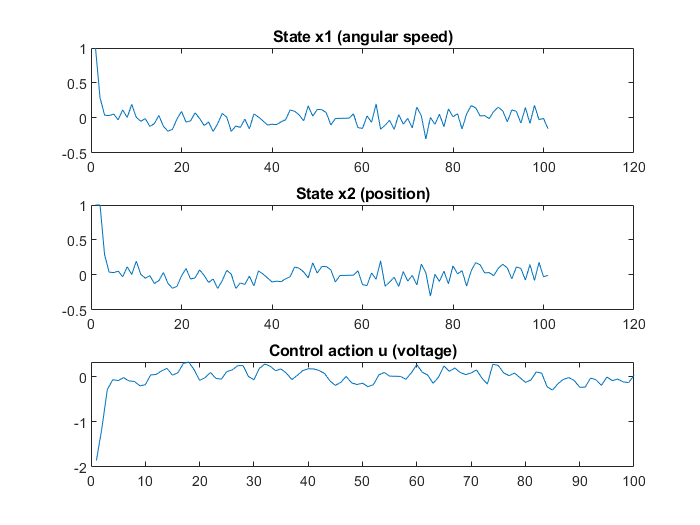

figure
subplot(3,1,1); plot(xopt(1,:)), title('State x1 (angular speed)')
subplot(3,1,2); plot(xopt(2,:)), title('State x2 (position)')
subplot(3,1,3); plot(uopt), title('Control action u (voltage)')

I don't know how and if this is the way to add disturbance and calculate it but it looks that it disturbs something. We can see that the disturbance creates big difference to previous optimizations.

### Activity 2. Dynamic programming method

In this activity we will try to solve the problem using dynamic programing and compare the solution with the previos ones.

First we initialize all the necesarry parameteres like before.

A=[1, 1; 1,0];      % system matrix
B=[1;0];            % control matrix
Q=eye(2);           % weight of states in obj function
S=Q;                % weight of final state in obj function
R=1;                % weight of control action in obj function
N=10;               % horizon

%Initialization
P=zeros(2,2,N+1);   % P matrix
K=zeros(1,2,N);     % gain
u=zeros(1,N);       % control action
x=zeros(2,1,N+1);   % states
x(:,1)=[1,1];       % initial conditions
P(:,:,N+1)=S;       % final state 

Then the created function dynamic_lqr is used. The inputs of this function are the number of iterations (N), the initialized vectors of the control action and the state variables (x,u), the P and K matrices initialized, and the A,B,R and Q matrices from the model.

[x,u,P,K]=dynamic_lqr(N,x,u,P,K,A,B,R,Q);
J_opt=0.5*x(:,:,1)'*P(:,:,1)*x(:,:,1);

The function executes the following code, where K and P are computed from k=N+1 to k=1.

function [x,u,P,K]=dynamic_lqr(k,x,u,P,K,A,B,R,Q)
    N=10;
    if k==1
        x(:,:,k)=[1,1]; % initial conditions
        K(:,:,k)=inv(R+B'*P(:,:,k+1)*B)*B'*P(:,:,k+1)*A;
        P(:,:,k)=Q+A'*P(:,:,k+1)*inv(eye(2)+B*inv(R)*B'*P(:,:,k+1))*A;
        u(k)=-K(:,:,k)*x(:,:,k);
    else
        K(:,:,k)=inv(R+B'*P(:,:,k+1)*B)*B'*P(:,:,k+1)*A;
        P(:,:,k)=Q+A'*P(:,:,k+1)*inv(eye(2)+B*inv(R)*B'*P(:,:,k+1))*A;
    
        %Invoking the function for k-1
        [x,u,P,K]=dynamic_lqr(k-1,x,u,P,K,A,B,R,Q);
        x(:,:,k)=A*x(:,:,k-1)+B*u(N-1);
        u(k)=-K(:,:,k)*x(:,:,k);
    end
end

As it can be seen, the function returns the control signal and the states variables, and the P and K vectors for each k.

Then we compute input and states as always.

for k=1:N
    u(k)=-K(:,:,k)*x(:,k);
    x(:,k+1)=A*x(:,k)+B*u(k);
end

In this graph we will compare all the optimization methods without constraints and disturbance.

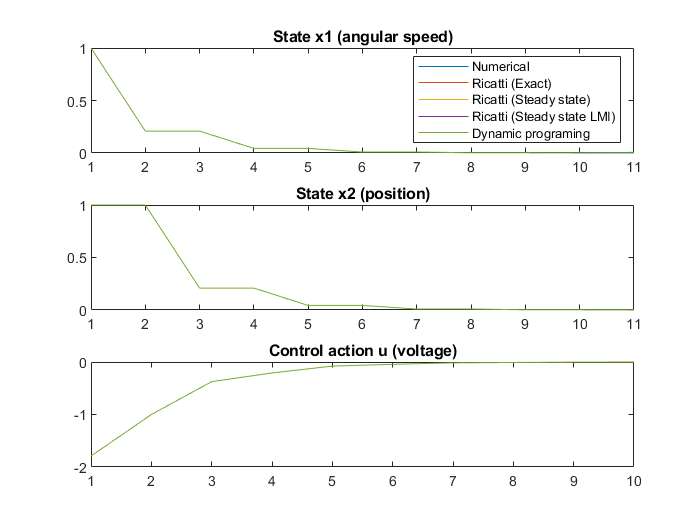

figure
subplot(3,1,1), plot(x_num(1,:)), title('State x1 (angular speed)'),hold on
plot(x_ex(1,:)),plot(x_aprox(1,:)),plot(x_LMI(1,:)),plot(x(1,:)),hold off
legend('Numerical','Ricatti (Exact)','Ricatti (Steady state)','Ricatti (Steady state LMI)','Dynamic programing')
subplot(3,1,2), plot(x_num(2,:)), title('State x2 (position)'),hold on
plot(x_ex(2,:)),plot(x_aprox(2,:)),plot(x_LMI(2,:)),plot(x(2,:)),hold off
subplot(3,1,3), plot(u), title('Control action u (voltage)'),hold on
plot(u_num),plot(u_ex),plot(u_aprox),plot(u_LMI),hold off

As we can see all the optimization methods have the same results within this control horizon.

function [x,u,P,K]=dynamic_lqr(k,x,u,P,K,A,B,R,Q)
    N=10;
    if k==1
        x(:,:,k)=[1,1]; % initial conditions
        K(:,:,k)=inv(R+B'*P(:,:,k+1)*B)*B'*P(:,:,k+1)*A;
        P(:,:,k)=Q+A'*P(:,:,k+1)*inv(eye(2)+B*inv(R)*B'*P(:,:,k+1))*A;
        u(k)=-K(:,:,k)*x(:,:,k);
    else
        K(:,:,k)=inv(R+B'*P(:,:,k+1)*B)*B'*P(:,:,k+1)*A;
        P(:,:,k)=Q+A'*P(:,:,k+1)*inv(eye(2)+B*inv(R)*B'*P(:,:,k+1))*A;
    
        %Invoking the function for k-1
        [x,u,P,K]=dynamic_lqr(k-1,x,u,P,K,A,B,R,Q);
        x(:,:,k)=A*x(:,:,k-1)+B*u(N-1);
        u(k)=-K(:,:,k)*x(:,:,k);
    end
end

